SAMPLE CODE

- Don't forget to add the relevant codes to your MATLAB path

% clear variables from workspace and close figures

clear
close all

% load in image series 
% for example, load sample simulation provided under demo/

uiopen('*.mat')

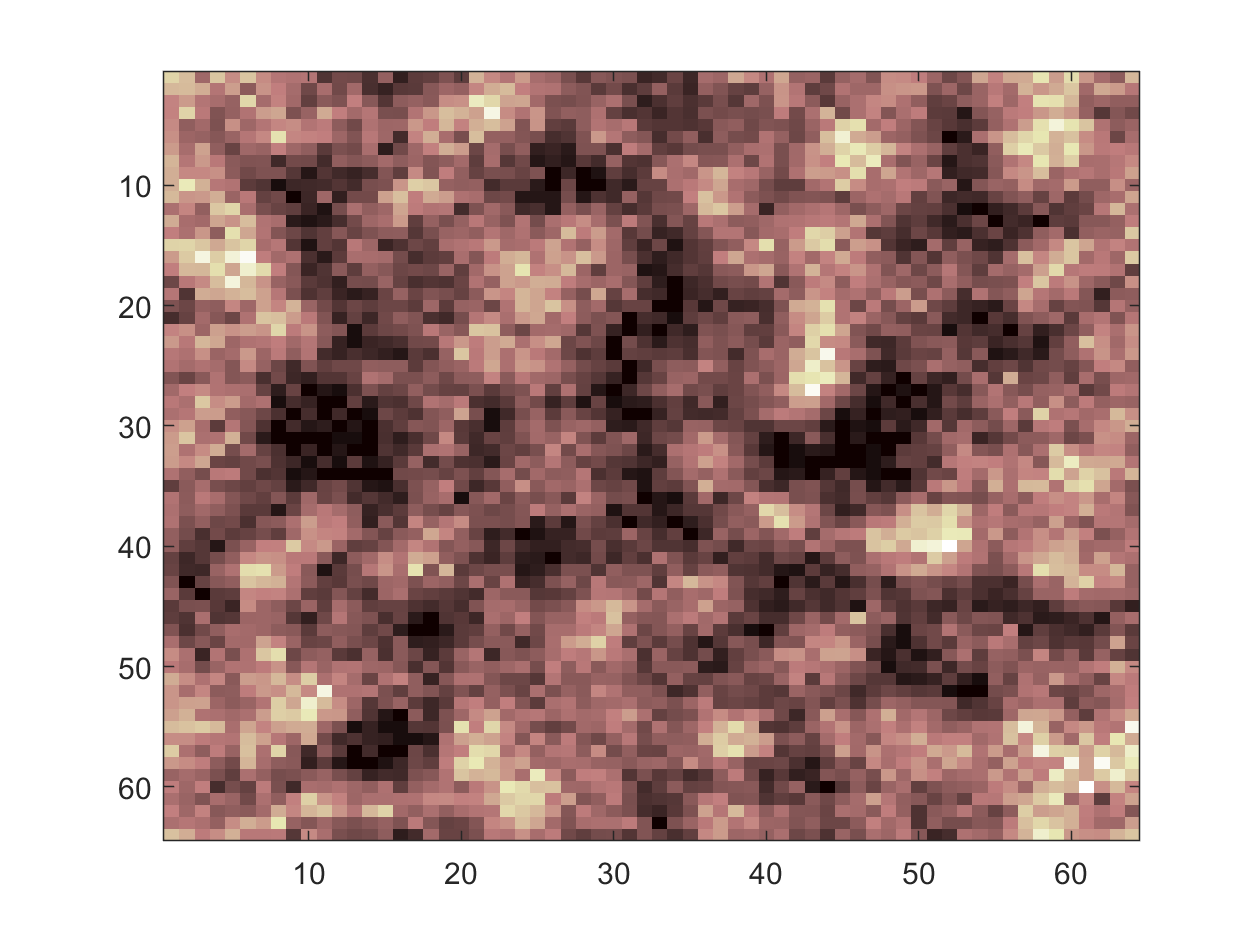

% view first image in image series

imagesc(J(:,:,1))
colormap(pink)

% get k-squared vector
%
% minimum k-squared value (non-zero, as k=0 is affected by noise)
ksq_min = 0.01;
% compute k-square vector, ksq, and indices, i_ksq
[ksq,i_ksq] = getKSqVector(J,'kSqMin',ksq_min);
%

% time-lag to analyze
tau = 1;

% compute kICS autocorrelation
r_k_tau = kICS(J,'subTempMean',0,'normByLag','none');
% circularly average kICS autocorrelation
r_k_tau_circ = circular(r_k_tau(:,:,tau+1));

% plot ACF over lag range tau_vec
plot(ksq,log(r_k_tau_circ(i_ksq)),'.','markersize',16);

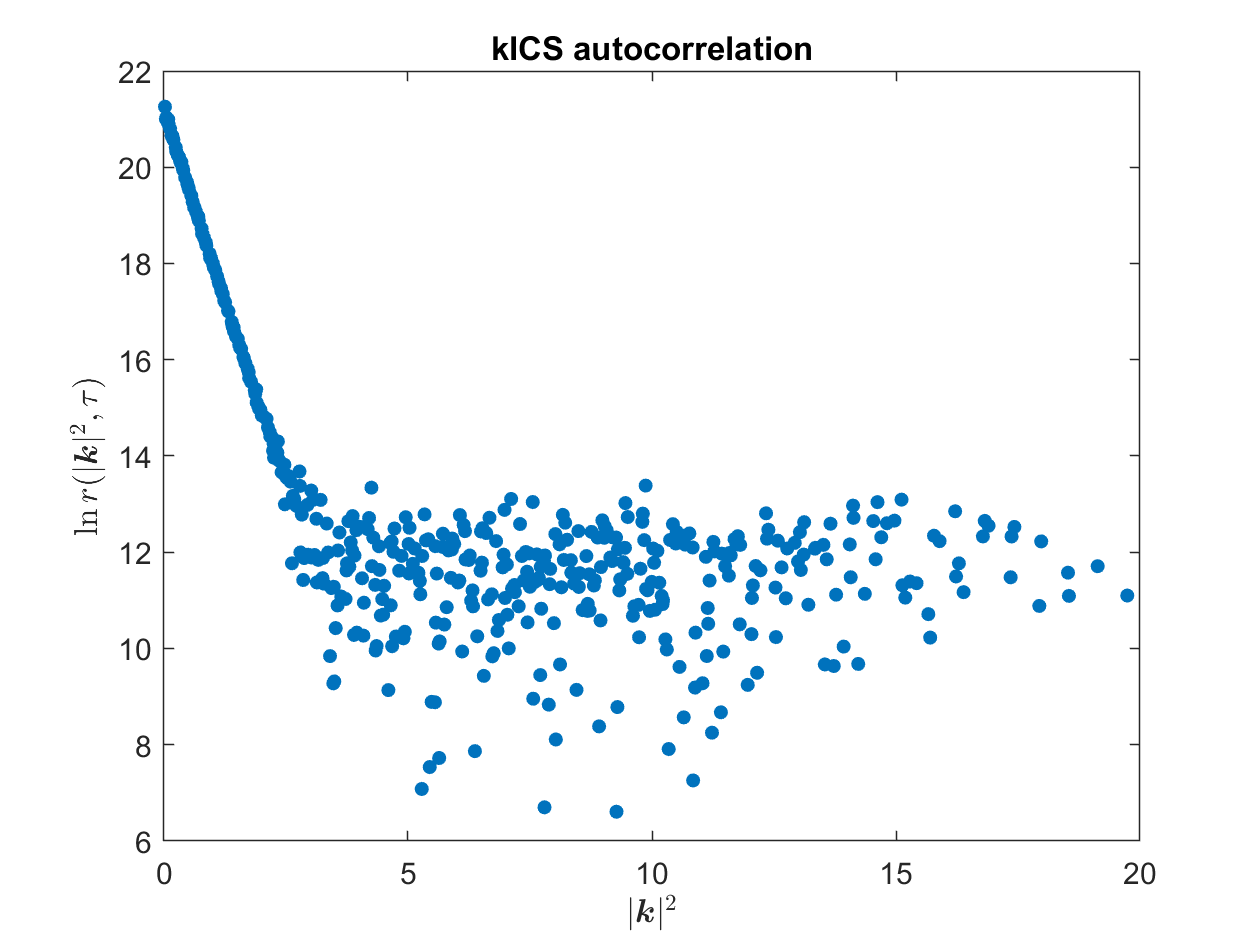

ax = gca;
title('kICS autocorrelation')
xlabel('$|${\boldmath$k$}$|^2$','Interpreter','latex')
ylabel('$\ln r(|${\boldmath$k$}$|^2,\tau)$','Interpreter','latex')